# 利用模拟滤波器在时间域进行滤波

clearvars;

## 滤波器示例：二阶高通巴特沃斯滤波器,截止频率为1Hz。

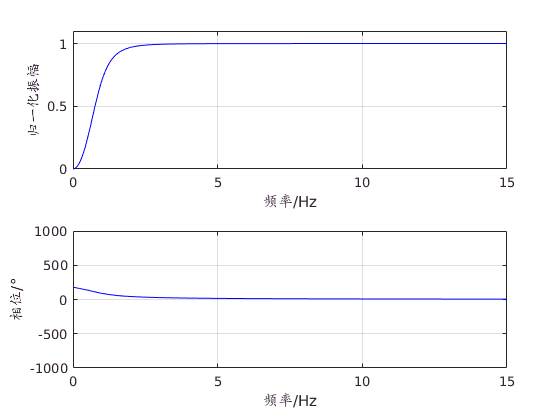

filOrd  = 2;                                   % 二阶
cutFre  = 1*2*pi;                              % 截止频率1Hz
[z,p,k] = butter(filOrd,cutFre,'high','s');    % 计算巴特沃斯低通滤波器幅频特性将
[b,a]   = zp2tf(z,p,k);                        % 系统函数的零极点转化为系统函数一
                                               % 般形式的系数，z为零点的值，p为极
                                               % 点的值，k为系数
[h,w]   = freqs(b,a);                          % 计算模拟滤波器的频率响应,h为幅度
                                               % 响应,w为模拟角频率
%--绘图---------------------------------------------------------------------
figure
subplot(2,1,1)
plot(w/(2*pi),abs(h),'b');hold on
axis([0 15 0 1.1])
ylabel('归一化振幅')
grid on
xlabel('频率/Hz')
subplot(2,1,2)
plot(w/(2*pi),unwrap(angle(h))*180/pi,'b');hold on
axis([0 15 -1000 1000])
grid on
ylabel('相位/°')
xlabel('频率/Hz')

## 构建与傅里叶变换得到的前段与后端共轭形式数据对应的滤波器

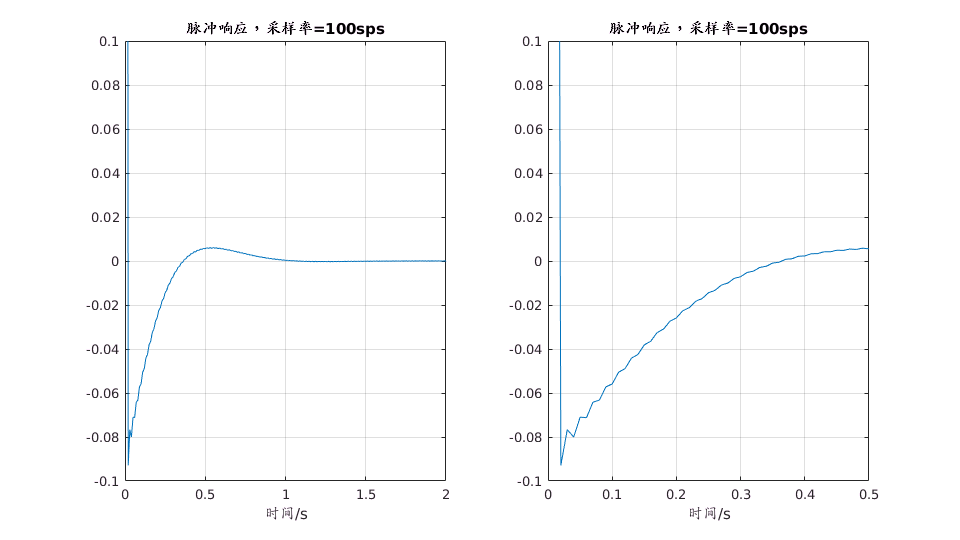

%万永革，2012，第429页）
%构造脉冲响应
Fs      = 100;                              % 采用率
datLen  = 60000;                            % 数据长度
freWav  = (1:datLen)*2*pi*Fs/datLen;        % 计算频率向量
resWav  = freqs(b,a,freWav);                % 计算模拟滤波器的频率响应
afreWav = freWav/(2*pi);
hzLen   = (1:datLen)/Fs;  
conWav  = zeros(1,datLen);
for i=1:datLen/2
    conWav(i) = resWav(i);
    conWav(datLen-i) = conj(resWav(i));
end
impule = real(ifft(conWav));

%--绘图---------------------------------------------------------------------
scrsz = get(groot,'ScreenSize');
figure('Position',[scrsz(3)/3 scrsz(4)/2 scrsz(3)/2 scrsz(4)/2]);
subplot(1,2,1)
plot(hzLen(1:datLen/2),impule(1:datLen/2))   %脉冲响应
axis([0 2 -0.1 0.1])
grid on
title('脉冲响应，采样率=100sps')
xlabel('时间/s')

subplot(1,2,2)
plot(hzLen(1:datLen/2),impule(1:datLen/2))   %脉冲响应
axis([0 0.5 -0.1 0.1])
grid on
title('脉冲响应，采样率=100sps')
xlabel('时间/s')

## 时间域滤波

读入示例地震波形：巴楚地震台CTS-1垂直向记录M7.72013年4月16日伊朗-巴基斯坦交界地震

wavDat  = load('XX_BCH_BHZ_2.txt');
wavDat  = wavDat(1:datLen);
%式（2.71）
timWav  = zeros(1,datLen);
impules = 2*Fs;
for i=1:datLen
   if i<impules+1
       for j=1:i
           timWav(i)=timWav(i)+wavDat(j)*impule(i-j+1);
       end
   end
   if i>impules
       for j=i-impules:i
           timWav(i)=timWav(i)+wavDat(j)*impule(i-j+1); 
       end
   end
end

fftWav1 = fft(wavDat);
fftWav2 = fft(timWav);

%???书中P39页图2.21上下两组图一样???
%--绘图---------------------------------------------------------------------
scrsz = get(groot,'ScreenSize');
figure('Position',[scrsz(3)/3 scrsz(4)/2 scrsz(3)/2 scrsz(4)/2]);
subplot(2,2,1)
plot(hzLen,wavDat)
xlabel('时间/s')
ylabel('count')

subplot(2,2,3)
plot(hzLen(1:datLen),timWav)
title('时间域滤波后')
xlabel('时间/s')
ylabel('count')

subplot(2,2,2)
loglog(afreWav(1:datLen/2),abs(fftWav1(1:datLen/2)))
title('滤波前')
xlabel('频率/Hz')
ylabel('谱振幅')

subplot(2,2,4)
loglog(afreWav(1:datLen/2),abs(fftWav2(1:datLen/2)))
title('滤波后')
xlabel('频率/Hz')
ylabel('谱振幅')